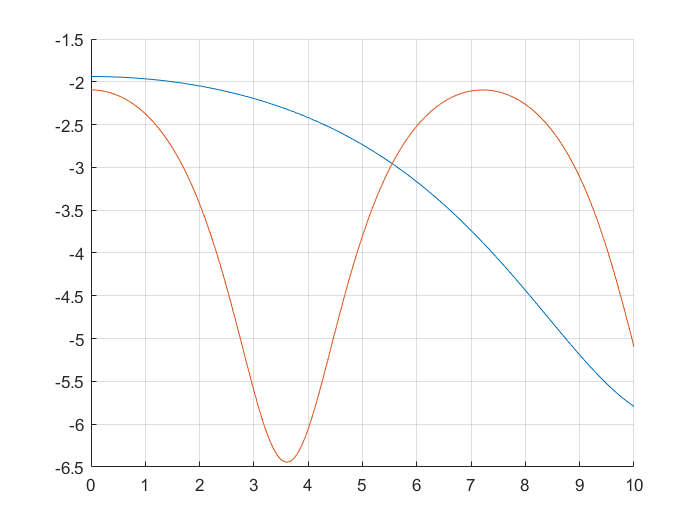

clear;

E_air = 1;
E_oil = 3;
theta = 0;
clf;
% planar -> ks = 0
% smooth -> ks = 0.2
% rough -> ks = 0.5
thickness = linspace(0, 10, 200);

raw12 = field_reflection_coefficient(sqrt(E_air), sqrt(E_oil));


%reflectivity at 4GHz
E_water_4GHz = RelDielConst_SalineWater(20,4,35);
raw23_4GHz = field_reflection_coefficient(sqrt(3), sqrt(E_water_4GHz));
R4 = reflectivity(4, thickness, E_oil, raw12, raw23_4GHz);


%12 GHz
E_Water_12GHz = RelDielConst_SalineWater(20,12,35);
raw23_12GHz = field_reflection_coefficient(sqrt(3), sqrt(E_Water_12GHz));

R_water_f4_planar = ones(1, 200) * ((sqrt(E_air) - sqrt(E_water_4GHz))/(sqrt(E_air) + sqrt(E_water_4GHz)))^2;

%reflectivity at 4GHz
E_water_4GHz = E_water(20, 35, 4);
raw23_4GHz = field_reflection_coefficient(sqrt(3), sqrt(E_water_4GHz));
R4 = reflectivity(4, thickness, E_oil, raw12, raw23_4GHz);

%12 GHz
E_Water_12GHz = E_water(20, 35, 12);
raw23_12GHz = field_reflection_coefficient(sqrt(3), sqrt(E_Water_12GHz));
R12 = reflectivity(12, thickness, E_oil, raw12, raw23_12GHz);

hold on;
plot(thickness, 10*log10(abs(R4)));
plot(thickness, 10*log10(abs(R12)));
grid on;
hold off;

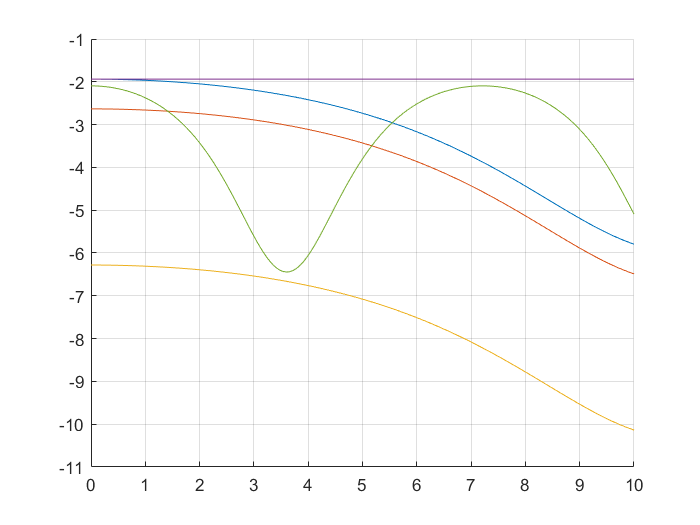

figure;

% % Figure 2
 hold on;
R_f4_planar = coherent_reflectivity(R4, 0, theta);
R_f4_smooth = coherent_reflectivity(R4, 0.2, theta);
R_f4_rough = coherent_reflectivity(R4, 0.5, theta);
R_water_f4_planar = ones(1, 200) * ((sqrt(E_air) - sqrt(E_water_4GHz))/(sqrt(E_air) + sqrt(E_water_4GHz)))^2;
R12 = reflectivity(12, thickness, E_oil, raw12, raw23_12GHz);
R_f12_planar = coherent_reflectivity(R12, 0, theta);



plot(thickness, 10*log10(abs(R_f4_planar)));
plot(thickness, 10*log10(abs(R_f4_smooth)));
plot(thickness, 10*log10(abs(R_f4_rough)));
plot(thickness, 10*log10(abs(R_water_f4_planar)));
plot(thickness,10*log10(abs(R_f12_planar)));
grid on;
hold off;

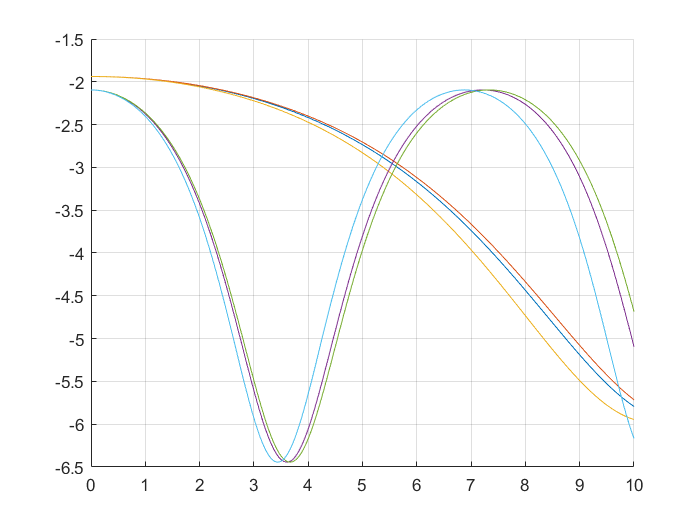

figure;

% %Figure 3
hold on;
plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(4, thickness, 3, raw12, raw23_4GHz),  0, theta))));
plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(4, thickness, 2.9, raw12, raw23_4GHz),  0, theta))));
plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(4, thickness, 3.3, raw12, raw23_4GHz),  0, theta))));
plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(12, thickness, 3, raw12, raw23_12GHz),  0, theta))));
plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(12, thickness, 2.9, raw12, raw23_12GHz),  0, theta))));
plot(thickness, 10*log10(abs(coherent_reflectivity(reflectivity(12, thickness, 3.3, raw12, raw23_12GHz),  0, theta))));
grid on;
hold off;

% clf;
% tic
% hold on;
% probability1 = probability_of_detection(1, [4 8 12], 0.5, 0.02, 1, 3, 0);
% probability2 = probability_of_detection(2, [4 8 12], 0.5, 0.02, 1, 3, 0);
% probability3 = probability_of_detection(3, [4 8 12], 0.5, 0.02, 1, 3, 0);
% probability4 = probability_of_detection(4, [4 8 12], 0.5, 0.02, 1, 3, 0);
% probability5 = probability_of_detection(5, [4 8 12], 0.5, 0.02, 1, 3, 0);
% probability6 = probability_of_detection(6, [4 8 12], 0.5, 0.02, 1, 3, 0);
% probability7 = probability_of_detection(7, [4 8 12], 0.5, 0.02, 1, 3, 0);
% 
% legend("1", "2", "3", "4", "5", "6", "7")
% grid on; 
% 
% 
% hold off;
% 
% toc

